### Auxilliary functions for better display :

- scale - takes the numbered samples and returns the time/frequency domain axis : $1\ldotp \ldotp \ldotp N\to 0\ldotp \ldotp \ldotp T$

- map - chooses the relative time stamp inside the new axis : $t_n \to \mathrm{idx}\left(t_n \right)$

clc ; clear ;

scale = @(N,T_s) (1:N).*(T_s/N);

map = @(y,x) floor(y * length(x)/x(end));

### Part 1 :

We are asked to create a square signal and sample it with the following characteristics:

- sample time - 1 sec

- sample rate - 3200khz

- signal base frequency - 250hz

- signal amplitude - based on equipment accuracy range...

We reconstruct the signal for 2 cases :

- reconstruct the signal as it is 

- applying anti-aliasing filter before reconstructing

Here are the results :

% Load variables
image_3_square_wave_filtered = load("C:\Users\yizha\coding\bgu\dsp_lab\lab3\part1\image_3_square_wave_filtered.mat");
square_without_anti_aliasing = image_3_square_wave_filtered.signal;
clear image_3_square_wave_filtered;

% Display results
square_without_anti_aliasing

square_without_anti_aliasing =     0.4265   -0.7275   -0.6009   -0.5515   -0.5174   -0.4907   -0.4650    0.4064    0.5316    0.5348    0.5176    0.4935    0.4695    0.3647   -0.6494   -0.5814   -0.5437   -0.5138   -0.4881   -0.4604    0.6080    0.5657    0.5410    0.5166    0.4896    0.4662    0.2346   -0.5694   -0.5593   -0.5369   -0.5082   -0.4845   -0.4575    0.7284    0.5921    0.5449    0.5160    0.4877    0.4636    0.0281   -0.5232   -0.5443   -0.5297   -0.5047   -0.4809   -0.4484    0.7456    0.5996    0.5462    0.5140


#### Signal without anti-aliasing filter (time domain):

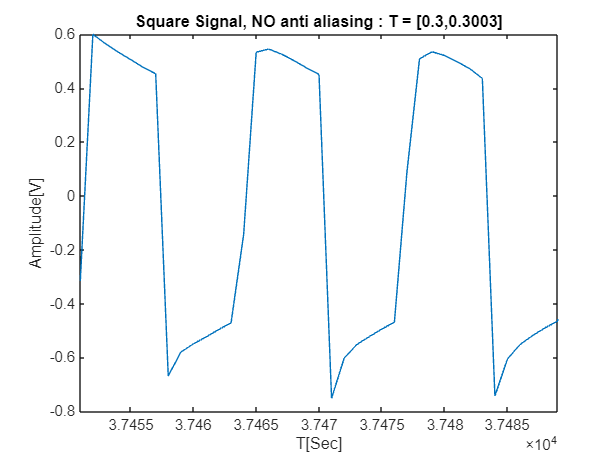

N_without = length(square_without_anti_aliasing);
Ts_without = 2;
T = scale(N_without,Ts_without);


figure;
plot(square_without_anti_aliasing);

title("Square Signal, NO anti aliasing : T = [0.3,0.3003]")

xlabel("T[Sec]")
ylabel("Amplitude[V]")

Lower_bound = map(0.3,T);
Upper_bound = map(0.3003,T);
xlim([Lower_bound,Upper_bound])

#### Signal without anti-aliasing filter (frequency domain):

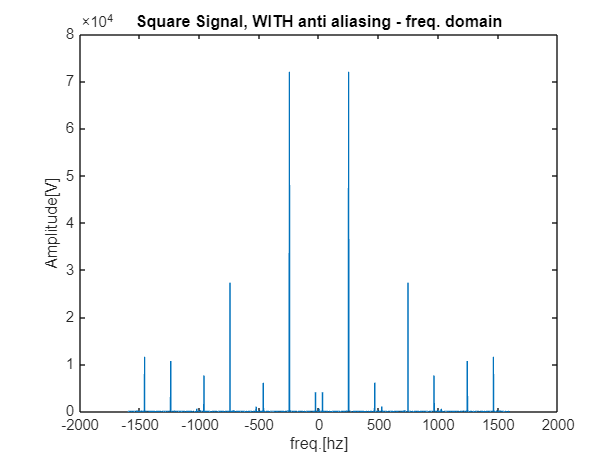

square_without_anti_aliasing_freq = fftshift(fft(square_without_anti_aliasing)) ;
fs_without = 3200 ;

f_without = scale(N_without,fs_without);
f_without = f_without - floor(fs_without/2);

figure;
plot(f_without,abs(square_without_anti_aliasing_freq));

title("Square Signal, WITH anti aliasing - freq. domain")

xlabel("freq.[hz]")
ylabel("Amplitude[V]")

% Load variables
image_4_square_wave_filtered_anti_aliasing = load("C:\Users\yizha\coding\bgu\dsp_lab\lab3\part1\image_4_square_wave_filtered_anti_aliasing.mat");
square_with_anti_aliasing = image_4_square_wave_filtered_anti_aliasing.signal;
clear image_4_square_wave_filtered_anti_aliasing;

% Display results
square_with_anti_aliasing

square_with_anti_aliasing =    -0.3658    0.5215    0.6061    0.5160    0.5257    0.4792    0.4561   -0.1183   -0.7346   -0.4868   -0.5639   -0.4855   -0.4852   -0.2549    0.6591    0.5384    0.5400    0.5017    0.4818    0.4239   -0.3394   -0.6845   -0.4978   -0.5512   -0.4839   -0.4777   -0.0883    0.7287    0.4926    0.5586    0.4867    0.4815    0.3664   -0.5115   -0.6208   -0.5193   -0.5333   -0.4835   -0.4640    0.1055    0.7287    0.4799    0.5563    0.4779    0.4799    0.2613   -0.6549   -0.5499   -0.5440   -0.5115


#### Signal WITH anti-aliasing filter:

N_with = length(square_with_anti_aliasing);
Ts_with = 2;
T = scale(N_with,Ts_with);


figure;
plot(square_with_anti_aliasing);

title("Square Signal, WITH anti aliasing : T = [0.3,0.3003]")

xlabel("T[Sec]")
ylabel("Amplitude[V]")
Lower_bound = map(0.3,T);
Upper_bound = map(0.32,T);
xlim([Lower_bound,Upper_bound])

#### Signal WITH anti-aliasing filter (frequency domain):

square_with_anti_aliasing_freq = fftshift(fft(square_with_anti_aliasing)) ;
fs_with = 3200 ;

f_with = scale(N_with,fs_with);
f_with = f_with - floor(fs_with/2);

figure;
plot(f_with,abs(square_with_anti_aliasing_freq));

title("Square Signal, WITH anti aliasing - freq. domain")

xlabel("freq.[hz]")
ylabel("Amplitude[V]")
figure ; 
hold on ;

plot(f_without,abs(square_without_anti_aliasing_freq)/max(abs(square_without_anti_aliasing_freq)), "--r");
plot(f_with,abs(square_with_anti_aliasing_freq)/max(abs(square_with_anti_aliasing_freq)), "--b");

hold off ;

### Part 2 :